                     %APPENDIX A%
Data_dBm = [-75 -73 -71.5 -71.5 -73 -73 -76.5 -81.5; ...
    -75 -72 -72 -72 -72 -73 -78 -80; ...
    -76.5 -74 -74 -75 -76.5 -76.5 -84.5 -84; ...
    -84 -79 -80 -84 -87.5 -87 -87 -87; ...
    -88.5 -96 -93 -86.5 -80 -85 -79 -81.5; ...
    -85 -88 -82 -81 -77.5 -77.5 -77.5 -80.5; ...
    -80 -83 -81.5 -81 -78.5 -78 -87 -81.5; ...
    -81 -82.5 -93 -87 -80 -80 -79 -85.5]

Data_dBm =   -75.0000  -73.0000  -71.5000  -71.5000  -73.0000  -73.0000  -76.5000  -81.5000
  -75.0000  -72.0000  -72.0000  -72.0000  -72.0000  -73.0000  -78.0000  -80.0000
  -76.5000  -74.0000  -74.0000  -75.0000  -76.5000  -76.5000  -84.5000  -84.0000
  -84.0000  -79.0000  -80.0000  -84.0000  -87.5000  -87.0000  -87.0000  -87.0000
  -88.5000  -96.0000  -93.0000  -86.5000  -80.0000  -85.0000  -79.0000  -81.5000
  -85.0000  -88.0000  -82.0000  -81.0000  -77.5000  -77.5000  -77.5000  -80.5000
  -80.0000  -83.0000  -81.5000  -81.0000  -78.5000  -78.0000  -87.0000  -81.5000
  -81.0000  -82.5000  -93.0000  -87.0000  -80.0000  -80.0000  -79.0000  -85.5000


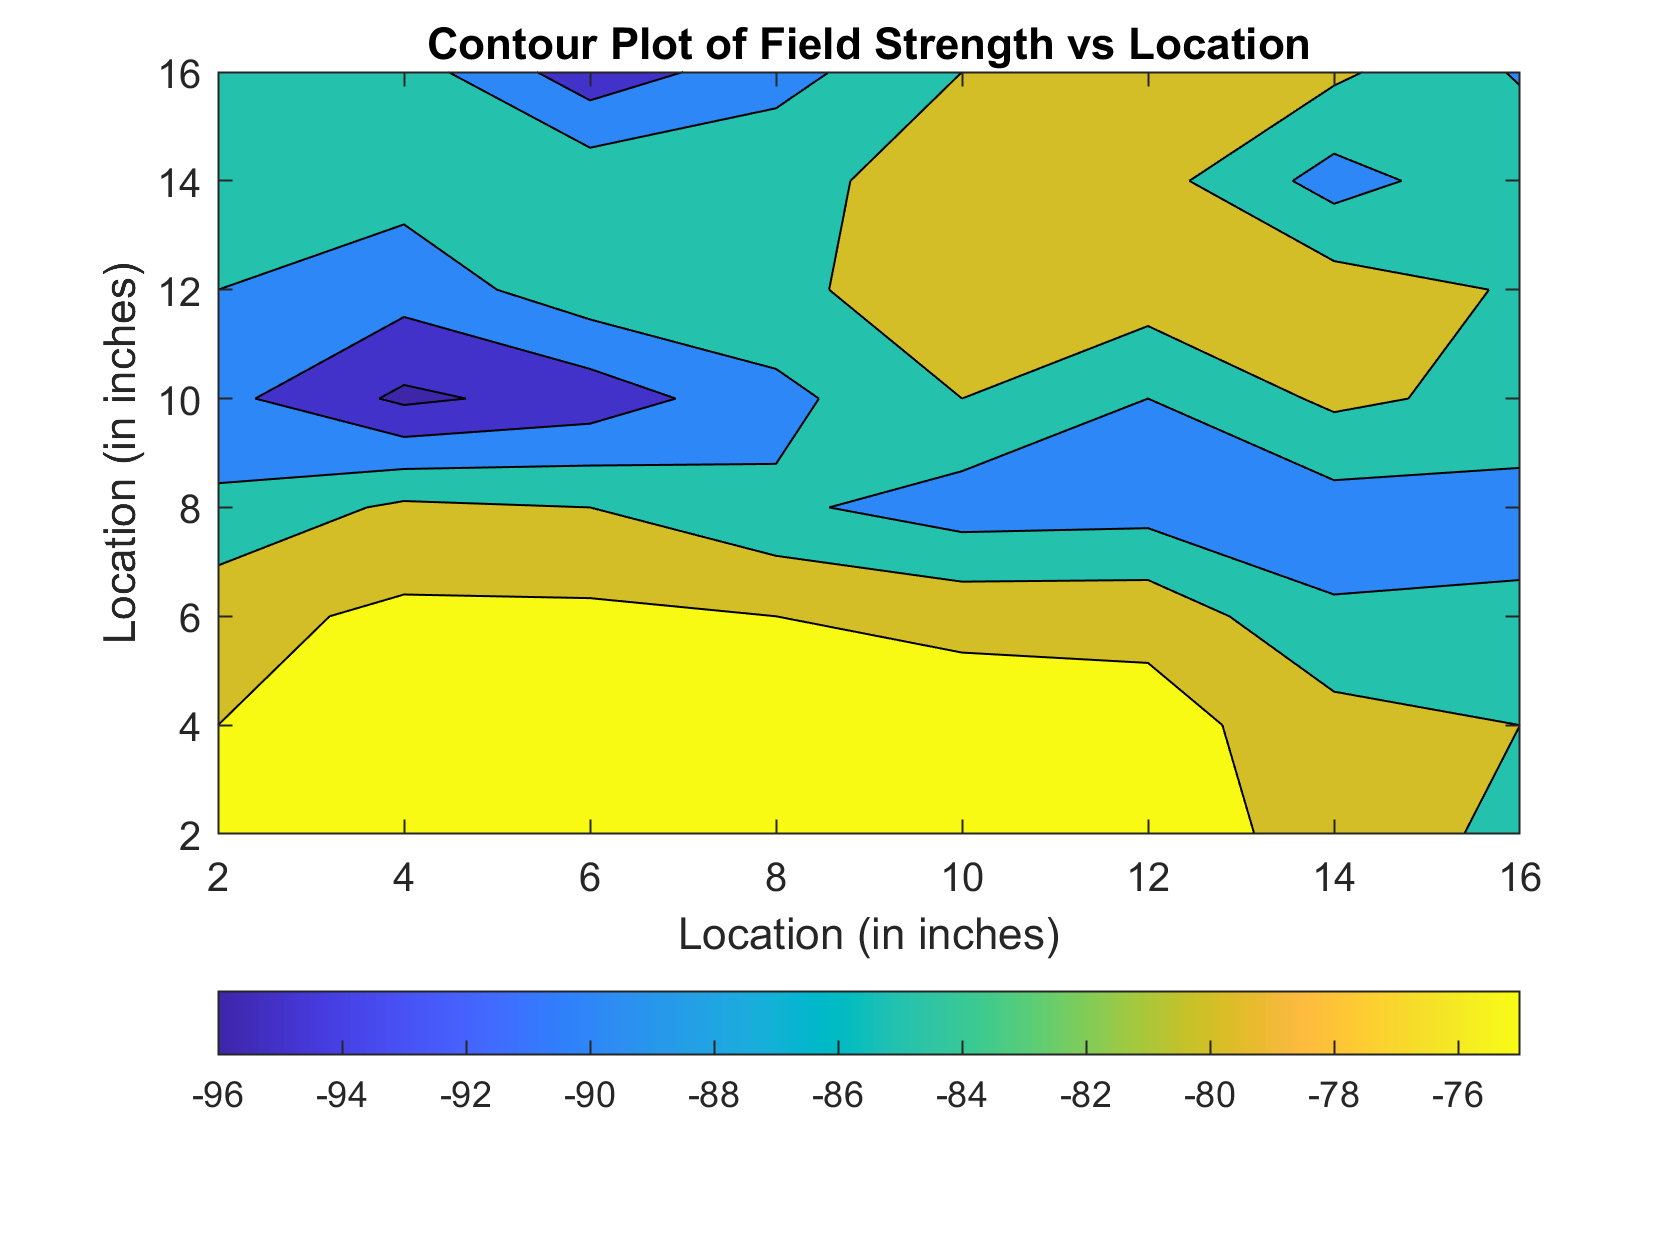

X = [2 4 6 8 10 12 14 16];
Y = [2; 4; 6; 8; 10; 12; 14; 16];

contourf(X, Y, Data_dBm)
title('Contour Plot of Field Strength vs Location') 
xlabel('Location (in inches)')
ylabel('Location (in inches)')
colorbar('southoutside')

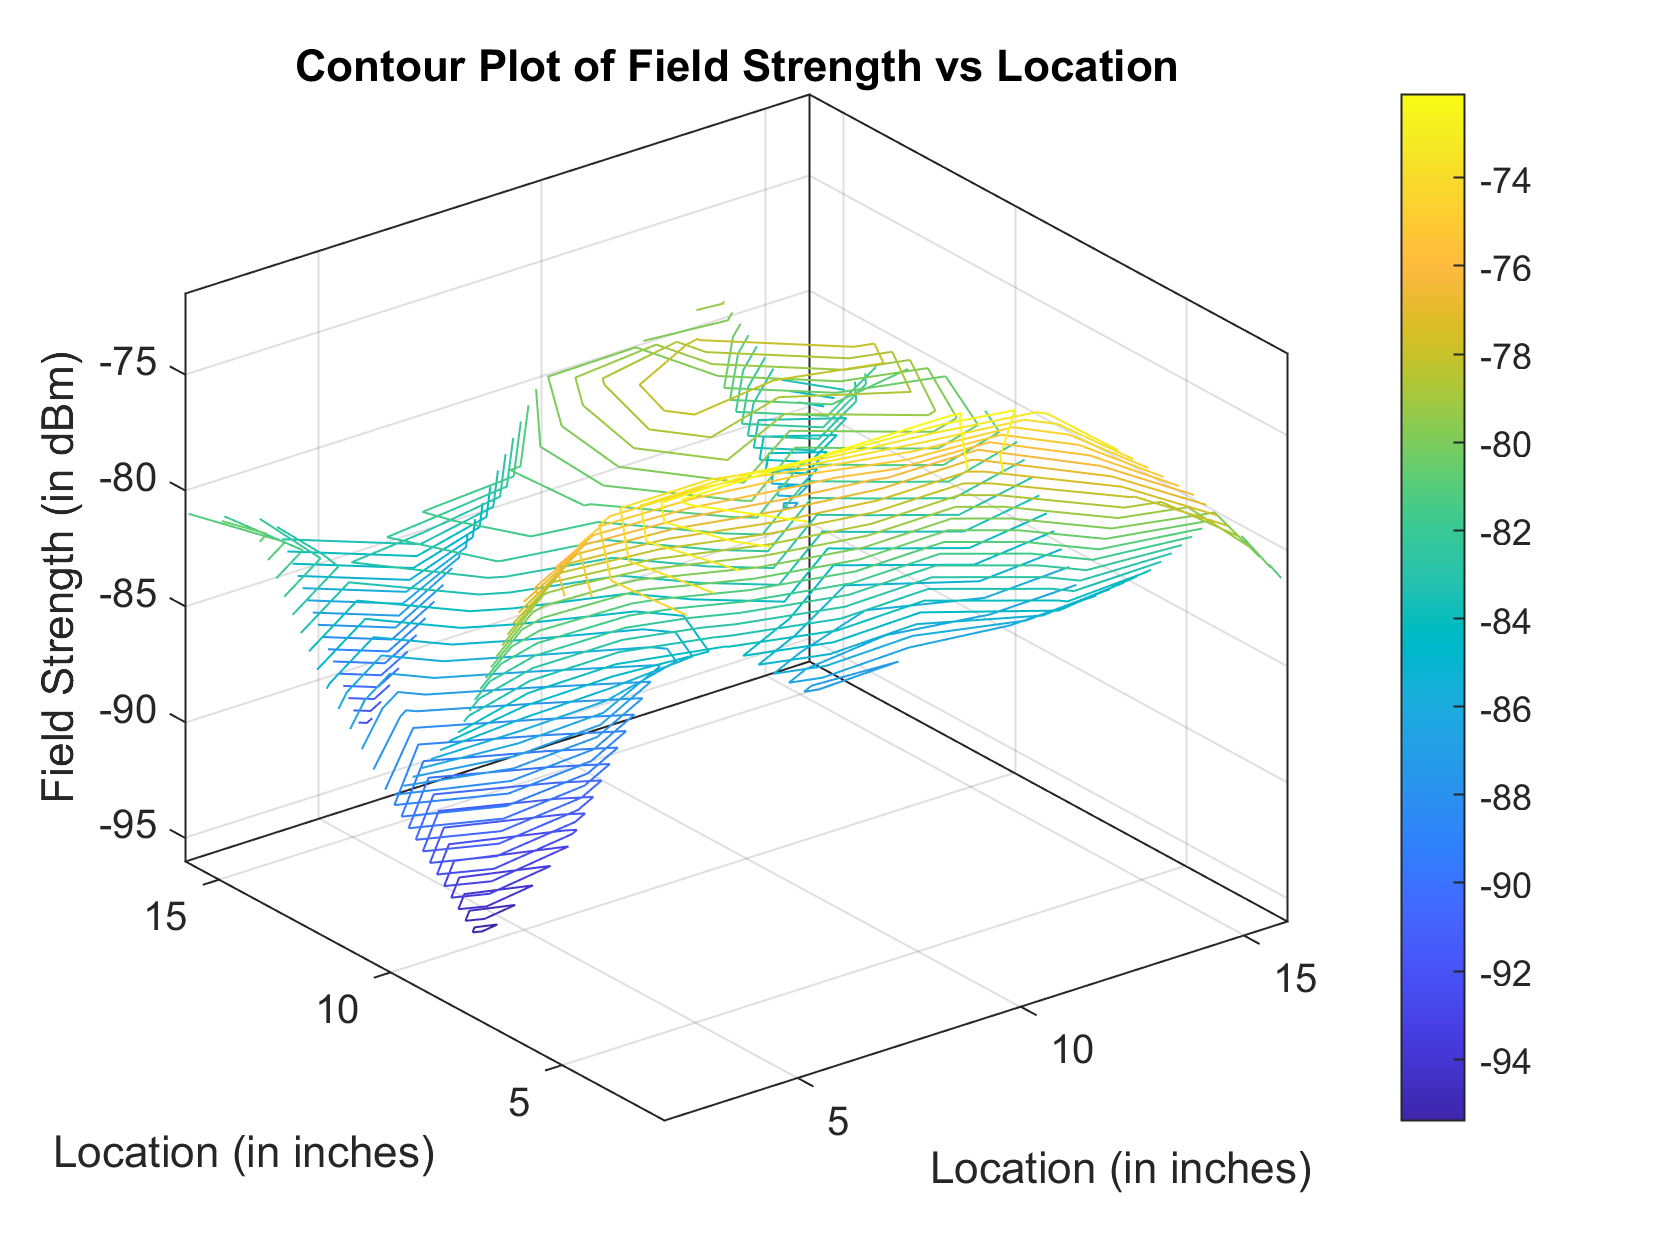

contour3(X, Y, Data_dBm, 40)
title('Contour Plot of Field Strength vs Location') 
xlabel('Location (in inches)')
ylabel('Location (in inches)')
zlabel('Field Strength (in dBm)')
colorbar


%Converting dBm to rms voltages across
%50 Ohms 
Voltage_rms = zeros(1,64);
var1 = zeros(1,64); %simpler 
for i = 1:64 %Need to populate 
    var1(i) = 10^(Data_dBm(i)/10);
    Voltage_rms(i) = sqrt(var1(i)/20);
end
M = mean(Voltage_rms)

M = 2.6063e-05

nbins = 10;
h = histogram(Voltage_rms, nbins)

h =   Histogram with properties:

             Data: [1×64 double]
           Values: [3 10 9 14 9 4 3 2 4 6]
          NumBins: 10
         BinEdges: [0 6.0000e-06 1.2000e-05 1.8000e-05 2.4000e-05 3.0000e-05 3.6000e-05 4.2000e-05 4.8000e-05 5.4000e-05 6.0000e-05]
         BinWidth: 6.0000e-06
        BinLimits: [0 6.0000e-05]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


title('Histogram of RMS Voltage values')
xlabel('Voltage (in V)')
ylabel('Number of Voltage Values') %should edit name
hold on
%Plot Theoretical Rayleigh Distribution
sigma = M/sqrt(pi/2)

sigma = 2.0795e-05

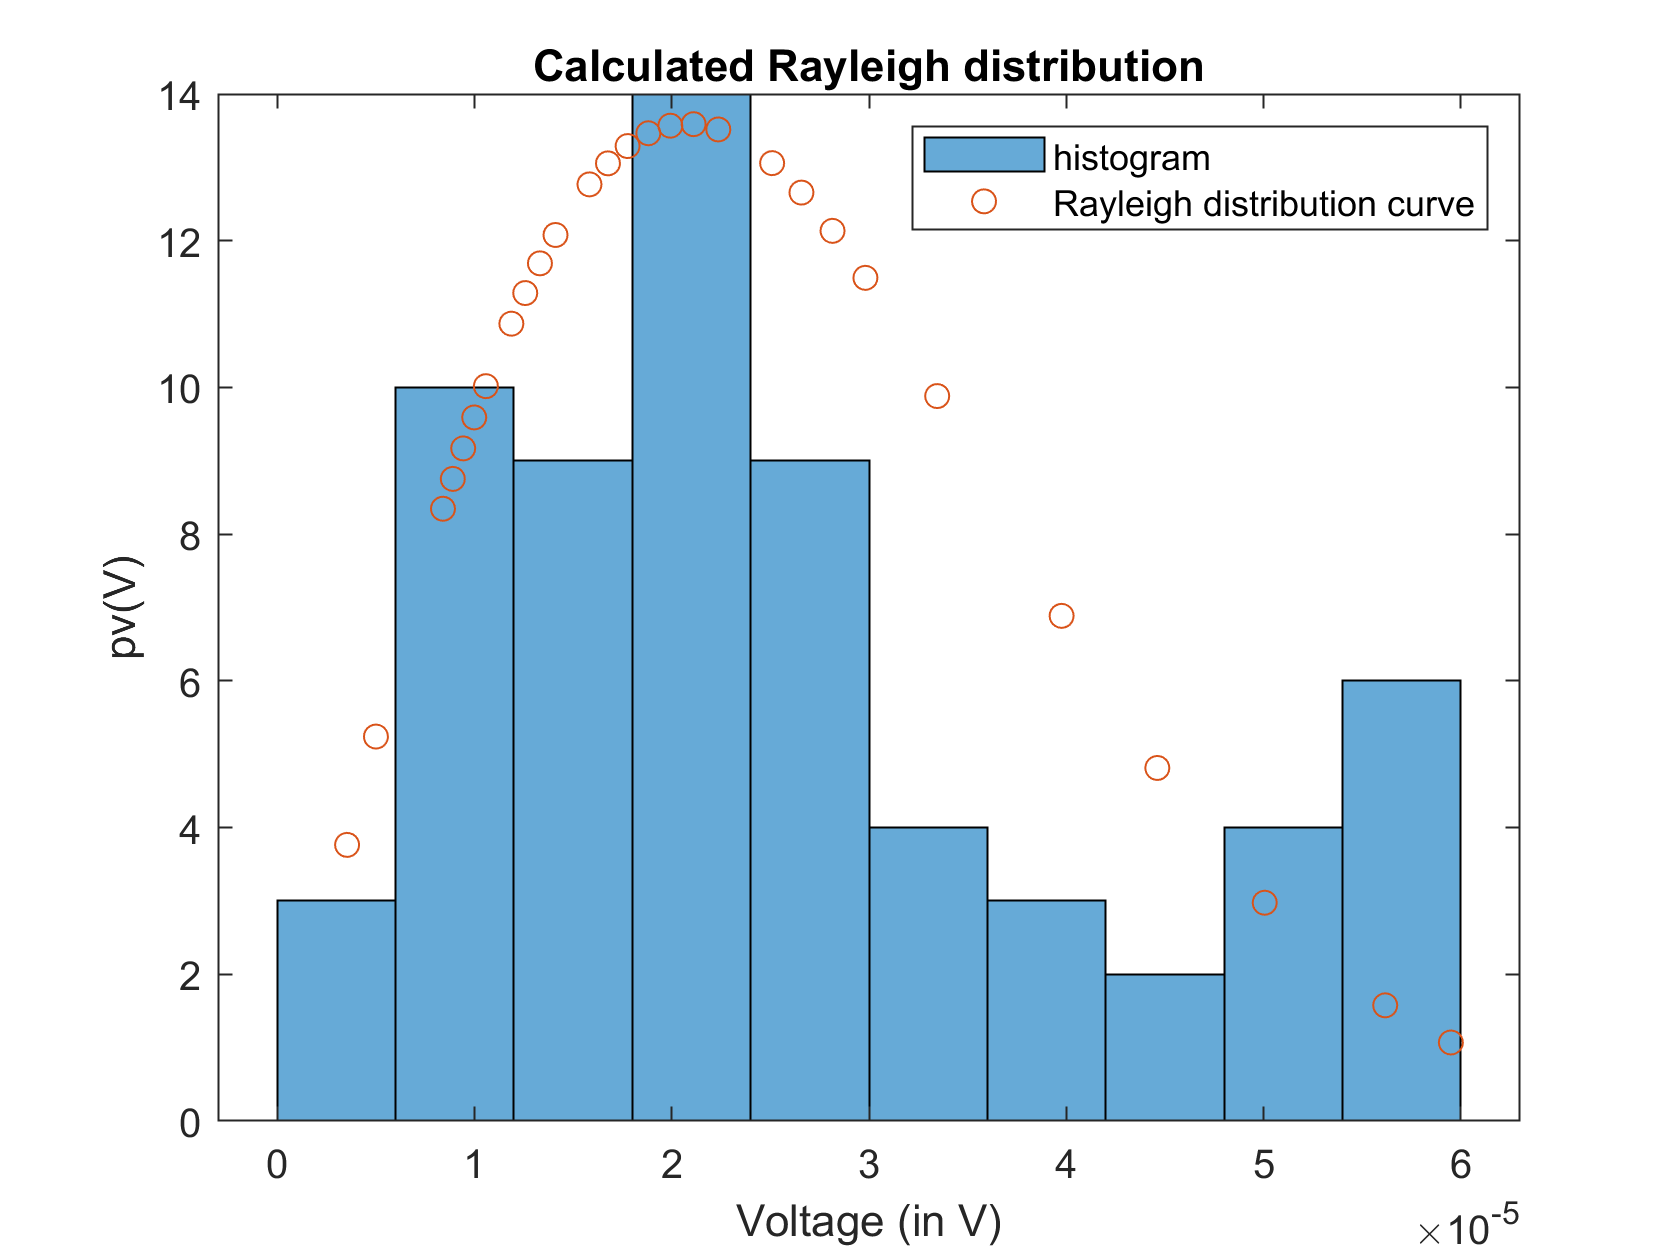

Rayleigh = zeros(1,64);
temp_exp = zeros(1,64);
for i = 1:64
    temp_exp(i) = exp(-((Voltage_rms(i)^2)/(2*(sigma^2))));
    Rayleigh(i) = (Voltage_rms(i)/(sigma^2))*temp_exp(i)*(4.66*10^-4);
end
temp_exp;
Rayleigh;
plot(Voltage_rms, Rayleigh, 'o')
title('Calculated Rayleigh distribution')
xlabel('Voltage (in V)')
ylabel('pv(V)')
legend('histogram', 'Rayleigh distribution curve')
hold off


%Using the Rayleigh command (to compare)
p = raylpdf(Voltage_rms,sigma);
%Chris Pinkham helped me with this portion
%Need to divide the distribution by its sum to get 
%probabilites
Rayleigh_sum = sum(p);
p = p / Rayleigh_sum %this gives probabilites 

p =     0.0113    0.0113    0.0162    0.0198    0.0137    0.0185    0.0222    0.0223    0.0049    0.0026    0.0079    0.0214    0.0062    0.0144    0.0210    0.0214    0.0018    0.0026    0.0079    0.0222    0.0086    0.0218    0.0221    0.0086    0.0018    0.0026    0.0113    0.0198    0.0164    0.0223    0.0223    0.0157    0.0049    0.0026    0.0162    0.0151    0.0222    0.0189    0.0208    0.0222    0.0049    0.0049    0.0162    0.0157    0.0185    0.0189    0.0199    0.0222    0.0162    0.0199


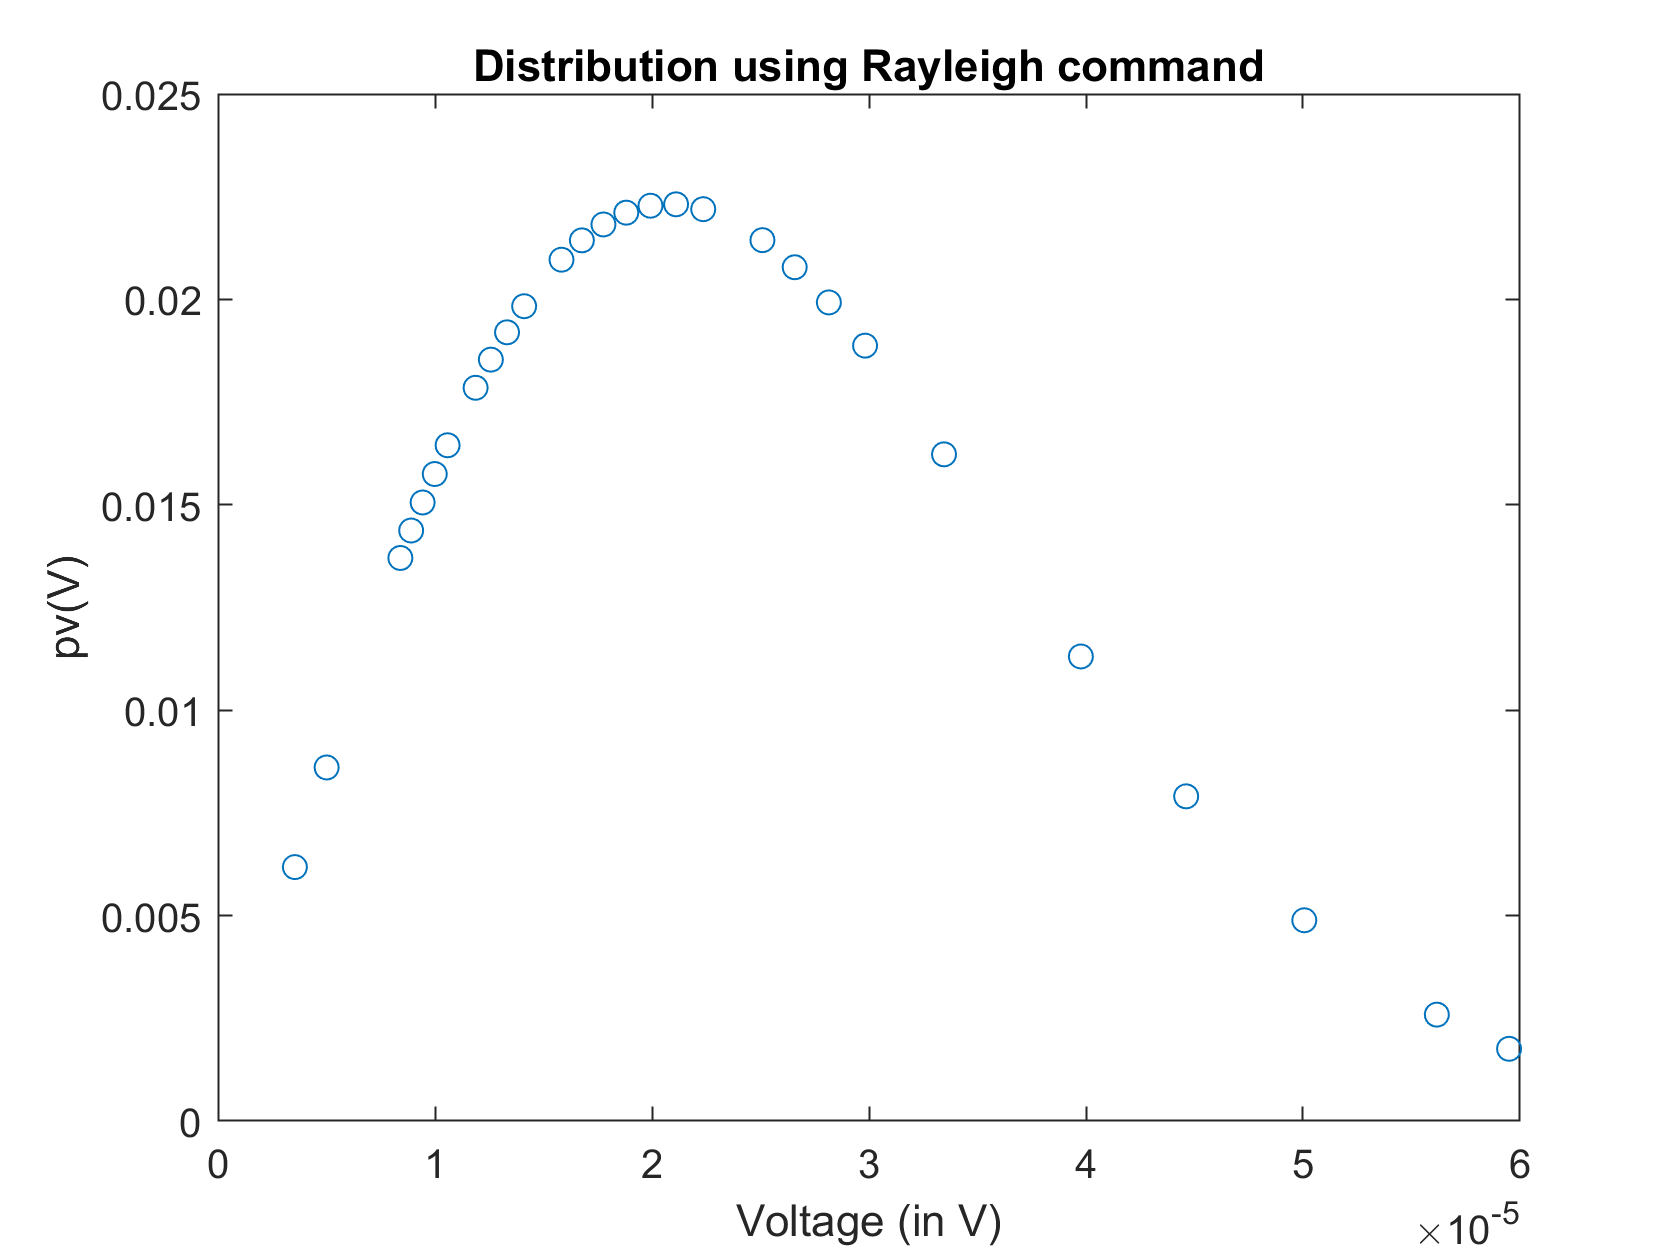

plot(Voltage_rms,p, 'o')
title('Distribution using Rayleigh command')
xlabel('Voltage (in V)')
ylabel('pv(V)')